rng(1405);
a = randi([0 10], [5 5])

a =      4     9     8     7     0
     3     6     1     8     0
     7     4     3     3    10
    10     2    10     1     6
     8     9     4     2     1


a(7)

ans = 6

aVec = a(:);
aVec(7 - size(a, 1) - 1)

ans = 4

aVec(7 - size(a, 1))

ans = 3

aVec(7 - size(a, 1) + 1)

ans = 7

aVec(7 - 1)

ans = 9

aVec(7 + 1)

ans = 4

aVec(7 + size(a, 1) - 1)

ans = 8

aVec(7 + size(a, 1))

ans = 1

aVec(7 + size(a, 1) + 1)

ans = 3


tmp1 = ones(size(a, 1), 1);
tmp1( 1 : 2 : end ) = 0;
tmp2 = ones( 1, size(a, 2 ) );
tmp2( 1 : 2 : end ) = 0;
whiteIndices = find( kron( tmp1, tmp2 ) )

whiteIndices =      7
     9
    17
    19


blackIndices = find( kron( ~tmp1, ~tmp2 ) )

blackIndices =      1
     3
     5
    11
    13
    15
    21
    23
    25


redIndices = find( kron( ~tmp1, tmp2 ) )

redIndices =      6
     8
    10
    16
    18
    20


greenIndices = find( kron( tmp1, ~tmp2 ) )

greenIndices =      2
     4
    12
    14
    22
    24



aVec(whiteIndices) = 1;
aVec(blackIndices) = 2;
aVec(redIndices) = 3;
aVec(greenIndices) = 4;

aVec = reshape(aVec, [5 5])

aVec =      2     3     2     3     2
     4     1     4     1     4
     2     3     2     3     2
     4     1     4     1     4
     2     3     2     3     2


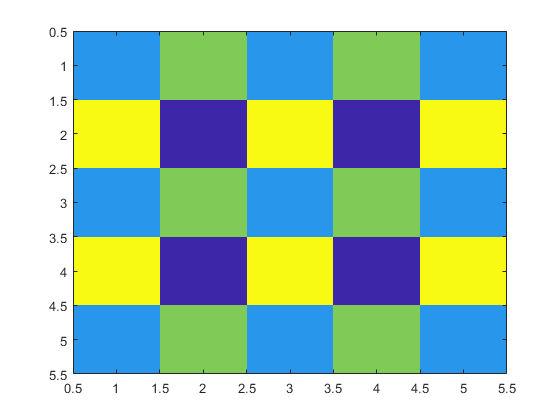


imagesc(aVec)


indicesToUpdateCell{1} = whiteIndices;
indicesToUpdateCell{2} = blackIndices;
indicesToUpdateCell{3} = redIndices;
indicesToUpdateCell{4} = greenIndices;

disp(indicesToUpdateCell)

    {4×1 double}    {9×1 double}    {6×1 double}    {6×1 double}

